## ***ENME403 Lab with the bois***

clear, close all, clc

**Define system parameters.**

%Constants
m1 = 1.608;      %(kg)       Cart 1 mass 
m2_u = 0.75;     %(kg)       Cart 2 mass unloaded
m3_u = m2_u;     %(kg)       Cart 3 mass unloaded
m2_l = 1.25;     %(kg)       Cart 2 mass loaded 
m3_l = m2_l;     %(kg)       Cart 3 mass loaded
k = 175;         %(N/m)      Spring constant
c1 = 0;          %(Ns/m)     Cart 1 damping
c2 = 3.68;       %(Ns/m)     Cart 2 damping
c3 = c2;         %(Ns/m)     Cart 3 damping
alpha = 12.45;   %(-)        Experimental fiddle factor
R = 1.4;         %(Ohms)     Motor terminal resistance
r = 0.0184;      %(m)        Pinion radius
k_g = 3.71;      %(-)        Gearing ratio
k_m = 0.00176;   %(Vs/rad)   Motor back EMF constant
v_lim = 12;      %(V)        Absolute voltage limit
slew_lim = 30;   %(V/s)      Absolute dv/dt
dx = 0.5;        %(m)        Step size of cart. This could be 0.5

%Matricies
m_matrix = [m1, 0, 0; 0, m2_l, 0; 0, 0, m3_l]

m_matrix =     1.6080         0         0
         0    1.2500         0
         0         0    1.2500


c_matrix = [c1+(k_m^2*k_g^2)/(R*r^2), 0, 0; 0, c2, 0; 0, 0, c3]

c_matrix =     0.0900         0         0
         0    3.6800         0
         0         0    3.6800


k_matrix = [k, -k, 0; -k, 2*k, -k; 0, -k, k]

k_matrix =    175  -175     0
  -175   350  -175
     0  -175   175


b_matrix = [(alpha*k_m*k_g)/(R*r); 0; 0]

b_matrix =     3.1558
         0
         0



A = [zeros(3), eye(3); -m_matrix\k_matrix, -m_matrix\c_matrix]

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
 -108.8308  108.8308         0   -0.0559         0         0
  140.0000 -280.0000  140.0000         0   -2.9440         0
         0  140.0000 -140.0000         0         0   -2.9440


B = [zeros(3,1); m_matrix\b_matrix]

B =          0
         0
         0
    1.9626
         0
         0


C = [0 0 1 0 0 0] % eye(6)

C =      0     0     1     0     0     0


D = 0

D = 0

**State space object**

sys = ss(A, B, C, D);

**Analyse**

CMatrix = ctrb(sys);
OMatrix = obsv(sys);

eig(sys);

Y_U = tf(sys);

[V, E] = eig(A);


**Design control gains**

Pole Method

poles = [-1+20i, -1-20i, -2+10i, -2-10i, -3.5+3i, -3.5-3i]; %LAB SET 1 2.5sec

%K = place(A, B, poles)

%K = [28.3, 1.8, 1.5, 4, 3, 1]


LQR Method

Q = diag([1, 1, 2500, 1, 1, 1]) %Lab set 1 6 seconds

Q =            1           0           0           0           0           0
           0           1           0           0           0           0
           0           0        2500           0           0           0
           0           0           0           1           0           0
           0           0           0           0           1           0
           0           0           0           0           0           1


%Q = diag([17, 6, 34, 10, 3, 5]); %Lab set 2 6 seconds
R = 1;
K = lqr(sys, Q, R)

K =    30.5583   14.6271    4.8346    5.6409    3.1925    2.7262


Define System

ACL = (A - B*K);
sys = ss(ACL, B, C, D);

%tracking gain N
N = -inv(C*inv(ACL)*B) 

N = 50.0200

%N = 31.6


**Responses**

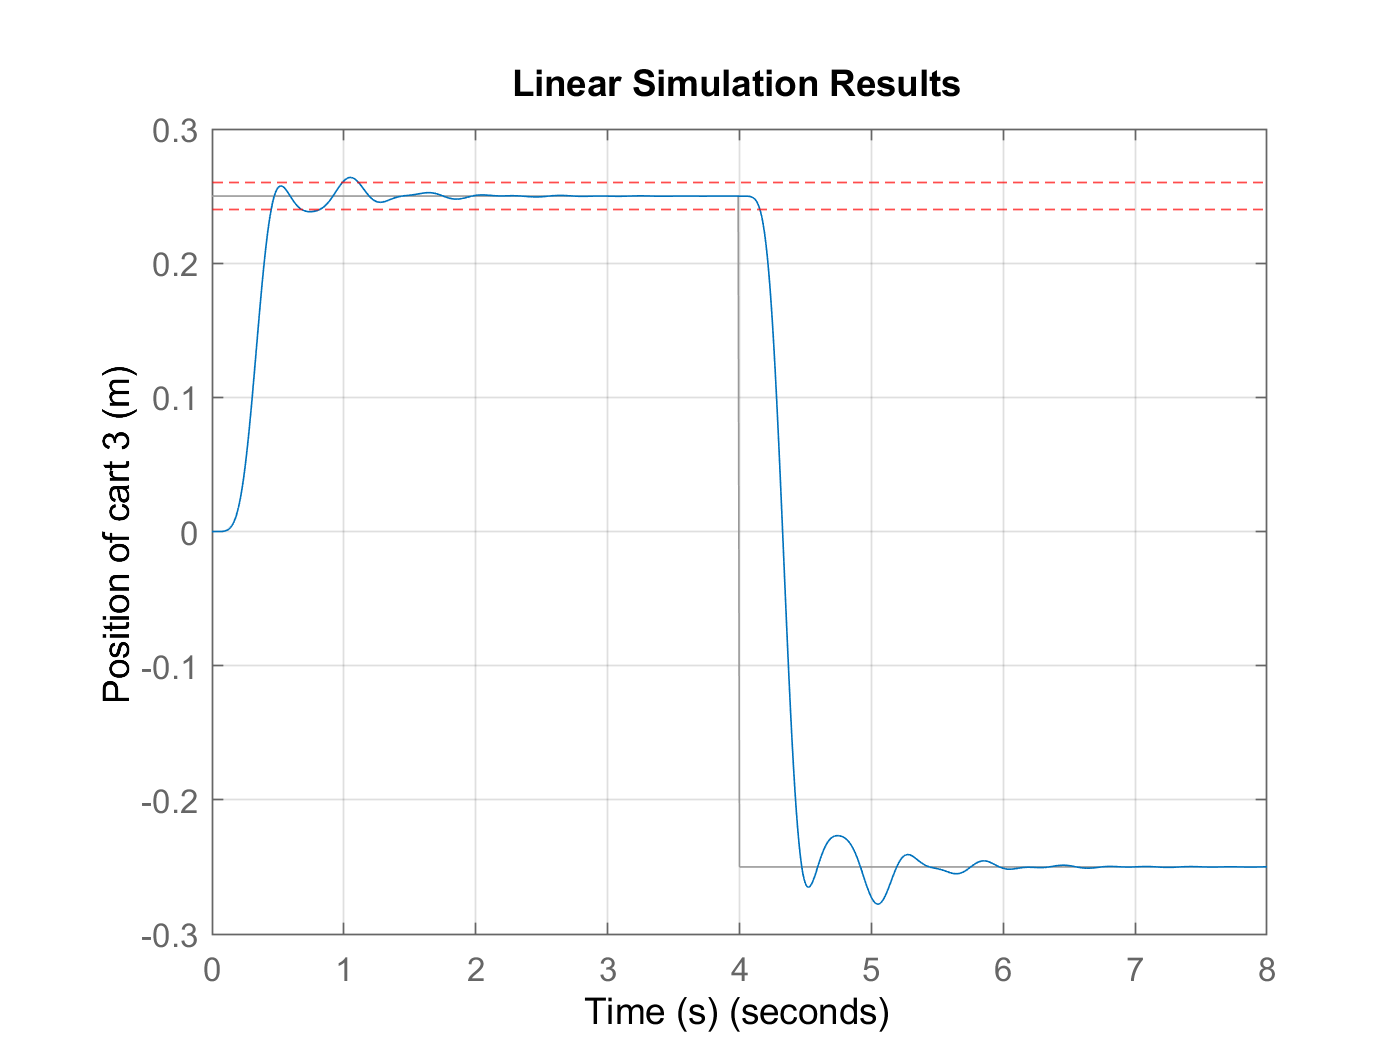

sys.B = N*sys.B; %As it is tracking a dx step input, also include tracking gain N

% Response plot
figure
dt = 0.01;
pulse_duration = 4; %seconds between tracking input steps 2.5sec
num_steps = 2; %number of steps back and forward
tArray = 0:dt:pulse_duration*num_steps; 
rArray = dx/2 .* ones(size(tArray));
for i = 1:2:num_steps-1
    rArray(i * pulse_duration/dt + 1: (i+1) * pulse_duration/dt + 1) = -1 * rArray(i * pulse_duration/dt + 1: (i+1) * pulse_duration/dt + 1); 
end

lsim(sys, rArray, tArray)
grid on
xlabel('Time (s)')
ylabel('Position of cart 3 (m)')
yline(dx/2+0.01,"--r")
yline(dx/2-0.01,"--r")

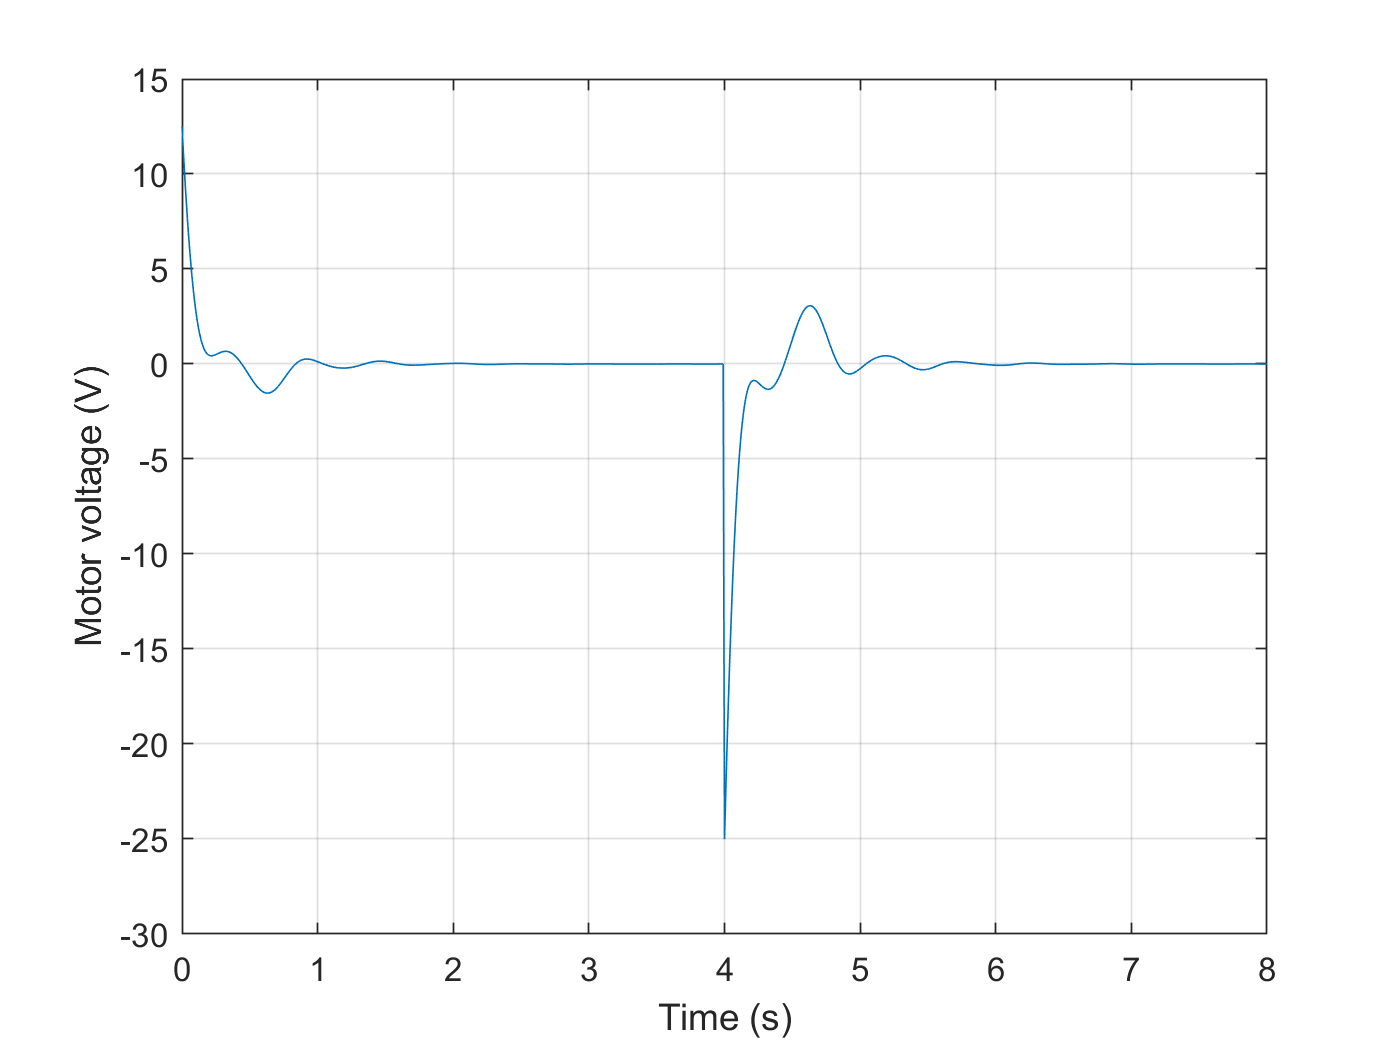


% Voltage
[y, t, x] = lsim(sys, rArray, tArray);
u = -K * x' + N * rArray;


plot(t, u)
grid on
xlabel('Time (s)')
ylabel('Motor voltage (V)')

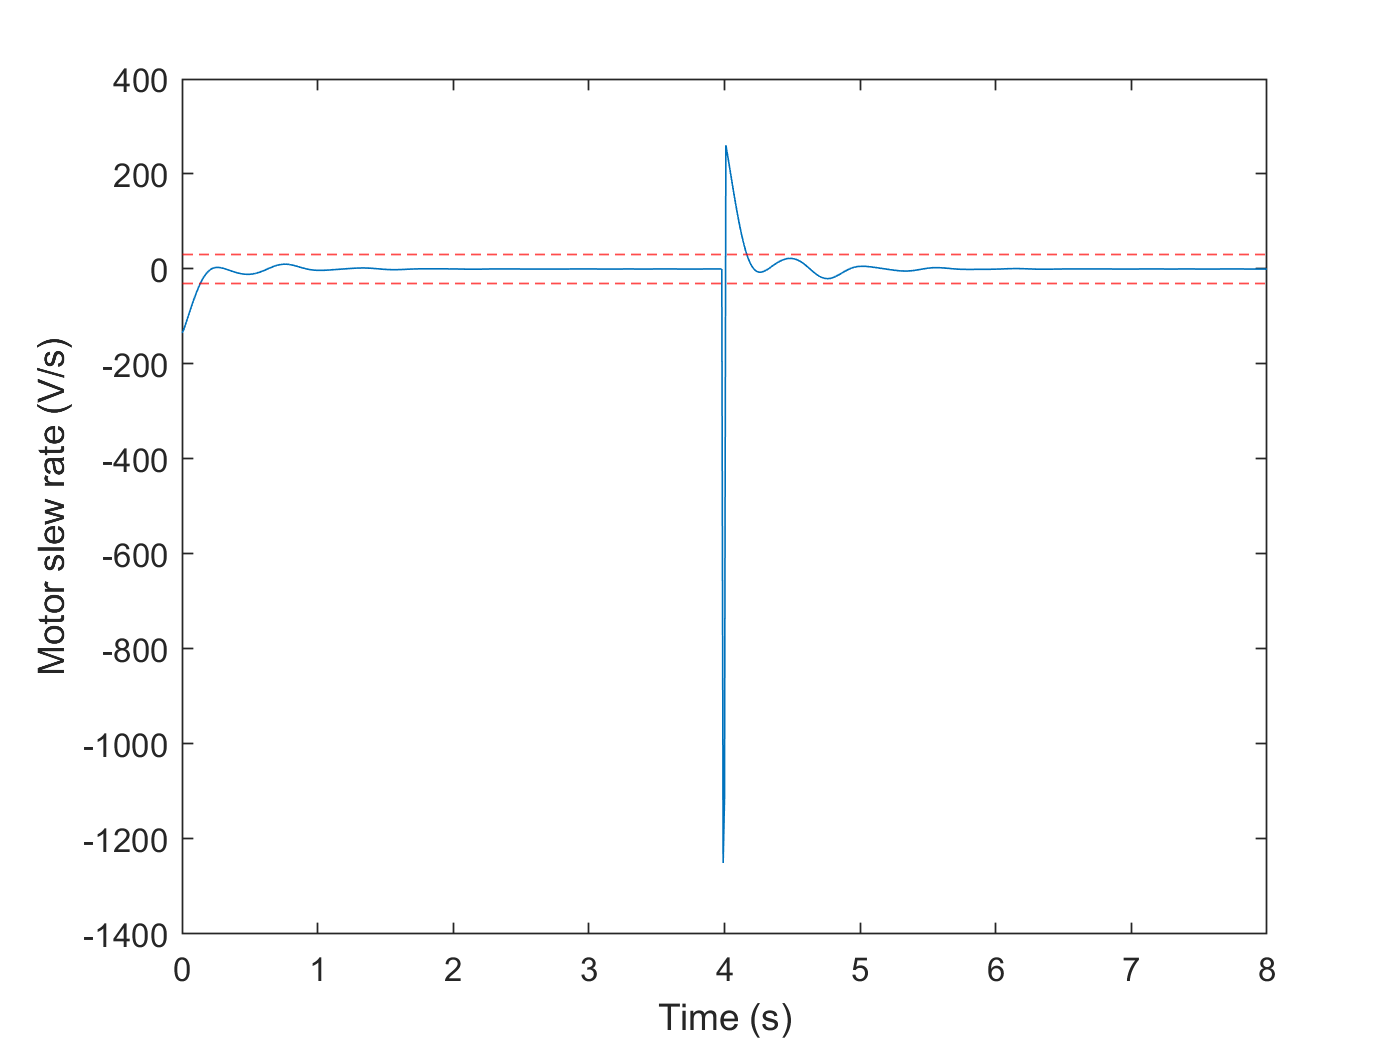


% Slew rate
dudt = gradient(u(:)) ./ gradient(t(:));


figure
plot(t, dudt)

xlabel('Time (s)')
ylabel('Motor slew rate (V/s)')
yline(30,"--r")
yline(-30, "--r")

disp(max(abs(dudt)))

   1.2505e+03

